## Procesamiento de datos

data = readmatrix('Flujo_delta_25a50.xlsx','Range','A377:C1471')

data =    30.0245   25.0000   20.5266
   30.0510   25.0000   20.2205
   30.0775   25.0000   20.4756
   30.1040   25.0000   20.1695
   30.1305   25.0000   20.6797
   30.1570   25.0000   20.1184
   30.1835   25.0000   20.3225
   30.2100   25.0000   19.9653
   30.2365   25.0000   20.2205
   30.2630   25.0000   19.5571


%data = readmatrix('Flujo_delta_25a50_sin_ruido.xlsx')

%data = readmatrix('Flujo_delta_25a50.xlsx')


t = data(:,1)-30;
u = data(:,2);
y = data(:,3);


yn = y - mean(y(1:10));
un = u - mean(u(1:10))

un =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


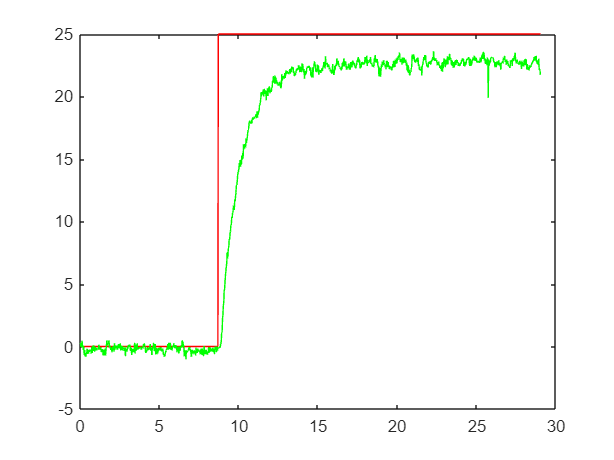


figure(1);
plot(t, un, 'r', t, yn, 'g');

%figure(2);
%plot(t, u, 'r', t, y, 'g');

## Identificación de parámetros

yf = mean(yn(1085:1095))

yf = 22.5397

yi = mean(yn(1:10))

yi = -3.5527e-15


uf = mean(un(1085:1095))

uf = 25

ui = mean(un(1:10)) 

ui = 0


deltay = yf - yi

deltay = 22.5397


deltau = uf - ui

deltau = 25


K = deltay/deltau

K = 0.9016


% Este método utiliza dos puntos 
% P_1->0.35deltay, P_2->0.85deltay 
delta_35 = 0.35*deltay

delta_35 = 7.8889

delta_85 = 0.85*deltay

delta_85 = 19.1587


y35 = yi + delta_35

y35 = 7.8889

y85 = yi + delta_85

y85 = 19.1587



% Se debe buscar el índice del valor solicitado
% Con ese índice se busca en el vector de tiempo
ind_35 = find(yn >= y35,1)

ind_35 = 353

%t35 = t(ind_35)-0.0265   
% Al tiempo correspondiente al índice se le resta un dato
t35 = t(ind_35)-8.48   %Modelo más preciso con 320 datos de tiempo antes     

t35 = 0.8725

ind_85 = find(yn >= y85,1)

ind_85 = 427

%t85 = t(ind_85)-0.0265
t85 = t(ind_85)-8.48   %Modelo más preciso con 320 datos de tiempo antes

t85 = 2.8335

## F.T

s = tf('s');

## **Método de Ho**

a=-0.670;b=0.670;
c=1.300;d=-0.290;
tau = a*t35 + b*t85

tau = 1.3139

tm = c*t35 + d*t85

tm = 0.3125


figure(1)
P_dp = K*exp(-tm*s)/(tau*s+1)

P_dp =
 
                    0.9016
  exp(-0.313*s) * -----------
                  1.314 s + 1
 
Continuous-time transfer function.



POMTM_Ho = lsim(P_dp,un,t);

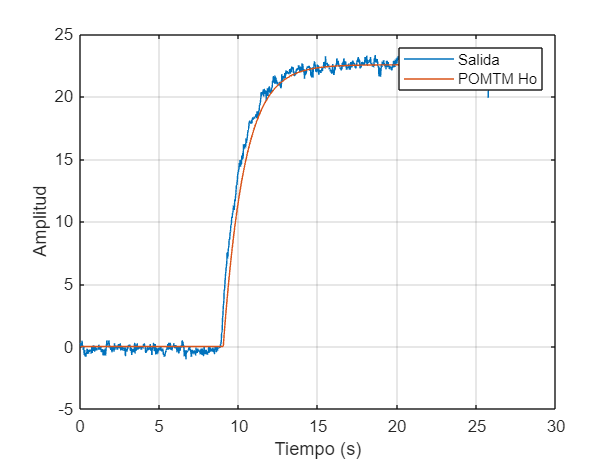


plot(t, yn, t,POMTM_Ho)
grid on
legend('Salida','POMTM Ho')
xlabel('Tiempo (s)')
ylabel('Amplitud')

## **IAE método Ho**


SalidaPlanta= yn;
SalidaModelo_1= POMTM_Ho; % Obtenido con toolbox
e_IAE=abs(SalidaPlanta-SalidaModelo_1);
IAE=trapz(t,e_IAE)

IAE = 12.7171